# Everage ERP Analysis

This code takes the epoches from each class (sick & non sick) and get a single averaged epoch per class. The averaging is performed seperately for each extraction method (i.e Activation Maximization & Sorting)

# Activation Maximization

clear;
load('C:\Users\Abdulsatar\Documents\UBICOMP\Thesis Work\ReverseNeuro\Results\Plots\trial21\Kfold_roi\maximization\matrix_jitter_output.mat');
participant_no = 29; % Number of participants
srate = 250;

summed_sick = int32(zeros(16,250));
summed_normal = int32(zeros(16,250));

for i = (1:participant_no)
    fieldName = ['field', num2str(i)];

    % Get the sick and normal samples
    sick_sample = export_matlab.(fieldName).sick;
    normal_sample = export_matlab.(fieldName).normal;

    summed_sick = summed_sick + sick_sample;
    summed_normal = summed_normal + normal_sample;
end

averaged_ERP_sick = summed_sick / participant_no;
averaged_ERP_normal = summed_normal / participant_no;

## Plot Average ERP

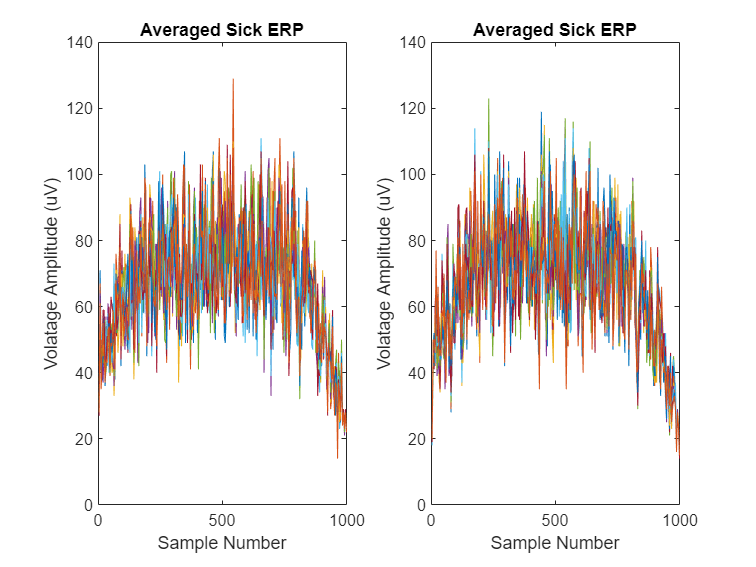

figure; % create a new figure
samples = (1:srate);
time = (samples*1000)/srate;
% Plot for matrix Sick
subplot(1,2,1); % Divide plot into 1 row, 2 columns, and select the first plot
for i = 1:size(averaged_ERP_sick, 1) % loop over rows
    plot(time, averaged_ERP_sick(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Averaged Sick ERP');
ylabel('Volatage Amplitude (uV)');
xlabel('Sample Number');
% ylim([0, 0.15]);

% Plot for matrix B
subplot(1,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(averaged_ERP_normal, 1) % loop over rows
    plot(time, averaged_ERP_normal(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Averaged Sick ERP');
ylabel('Volatage Amplitude (uV)');
xlabel('Sample Number');

% ylim([0, 0.15]);

# Sorting

clear;
load('C:\Users\Abdulsatar\Documents\UBICOMP\Thesis Work\ReverseNeuro\Results\Plots\trial21\Kfold_pruned\sorting\matrix_jitter_output.mat');
srate = 250;
sample_no = 29;

% BEST SAMPLE VARIABLES 
t_s_summed = zeros(16, srate); % The sum of the channel across subjects (16 X 250) => (Channels X Samples)
t_n_summed = zeros(16, srate); % The sum of the channel across subjects (16 X 250) => (Channels X Samples)

% WORST SAMPLE VARIABLES
f_s_summed = zeros(16, srate); % The sum of the channel across subjects (16 X 250) => (Channels X Samples)
f_n_summed = zeros(16, srate); % The sum of the channel across subjects (16 X 250) => (Channels X Samples)

for i = (1:sample_no)
    fieldName = ['field', num2str(i)];

    % GET THE SAMPLES
    % Get the best sick and normal samples
    true_sick_sample = export_matlab.(fieldName).true_sick;
    true_normal_sample = export_matlab.(fieldName).true_normal;

    % Get the worst sick and normal samples
    false_sick_sample = export_matlab.(fieldName).false_sick;
    false_normal_sample = export_matlab.(fieldName).false_normal;

    % GET THE SPECTRAS
    % Get the best spectra and their respective frequncies for both classes
    if ~isempty(true_sick_sample)
        t_s_summed = t_s_summed + mean(true_sick_sample, 3);
    end
    if ~isempty(true_normal_sample)
        t_n_summed = t_n_summed + mean(true_normal_sample, 3);
    end

    % Get the worst spectra and their respective frequncies for both classes
    if ~isempty(false_sick_sample)
       f_s_summed = f_s_summed + mean(false_sick_sample, 3);     
    end
    if ~isempty(false_normal_sample)
        f_n_summed = f_n_summed + mean(false_normal_sample, 3);
    end

end

% GET THE AVERAGED ERP
averaged_ERP_t_s = t_s_summed / sample_no;
averaged_ERP_t_n = t_n_summed / sample_no;
averaged_ERP_f_s = f_s_summed / sample_no;
averaged_ERP_f_n = f_n_summed / sample_no;

## Plot Averaged ERP

figure; % create a new figure
samples = (1:srate);
time = (samples*1000)/srate;
% Plot for matrix Sick
subplot(2,2,1); % Divide plot into 1 row, 1 columns, and select the first plot
for i = 1:size(averaged_ERP_t_s, 1) % loop over rows
    plot(time,averaged_ERP_t_s(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Average ERP of True Sick Sample');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
ylim([-4, 4]);

subplot(2,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(averaged_ERP_t_n, 1) % loop over rows
    plot(time,averaged_ERP_t_n(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Average ERP of True Non Sick Sample');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
ylim([-4, 4]);

subplot(2,2,3); % Divide plot into 2 row, 1 columns, and select the first plot
for i = 1:size(averaged_ERP_f_s, 1) % loop over rows
    plot(time,averaged_ERP_f_s(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Average ERP of False Sick Sample');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
ylim([-4, 4]);

subplot(2,2,4); % Divide plot into 2 row, 2 columns, and select the first plot
for i = 1:size(averaged_ERP_f_n, 1) % loop over rows
    plot(time,averaged_ERP_f_n(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Average ERP of False Non Sick Sample');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
ylim([-4, 4]);